**Lead-lag compensator** $K\frac{s+a}{s+b}$ design for $G(s)H(s)=\frac{1}{(s+1)(s+2)(s+3)}$

Set the design parameters:

clc
clearvars
close all
Mp= 0.02; %overshoot
ts = 5; %settling time
z = log(Mp)/sqrt((log(Mp))^2+pi^2); %damping ratio
wn = 4/(ts*z); %natural frequency
pd = roots([1 2*z*wn wn^2]) %desired poles 

pd =   -0.8000 + 0.6424i
  -0.8000 - 0.6424i


We now compute the angles of the open-loop poles against the desired poles. This values will permit us to obtain the zero/pole location of the lead-lag compensato through the root locus rules (I followed [https://www.ece.mcmaster.ca/~davidson/EE3CL4/slides/Lead_Lag_handout.pdf](https://www.ece.mcmaster.ca/~davidson/EE3CL4/slides/Lead_Lag_handout.pdf)).

t1 = atan(imag(pd(1))/(0.2))*180/pi

t1 = 72.7082

t2 = atan(imag(pd(1))/(1.2))*180/pi

t2 = 28.1634

t3 = atan(imag(pd(1))/(2.2))*180/pi

t3 = 16.2790

We impose the compensator pole at the origin. i.e. we will tune a classical PI control. PI control allow us zero steady state error.

t4 = atan(abs(real(pd(1))/imag(pd(1))))*180/pi+90 

t4 = 141.2334

angp = t1+t2+t3+t4

angp = 258.3840

According to root locus $\angle Z-\angle P=180^\degree(2\ell+1)$ , therefore the angle of the zero in the lead-lag compensator is

angz= -180+angp 

angz = 78.3840

Its location:

d = imag(pd(1))/tan((angz*pi/180))

d = 0.1321

zc = -d+real(pd(1))

zc = -0.9321

pc = 0 % pole of the compensator located by design at the origin

pc = 0

Open loop root locus (NOTE that I assumed H(s)=1 for simplicity)

s = tf('s');
G= 1/((s+1)*(s+2)*(s+3))

G =
 
            1
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


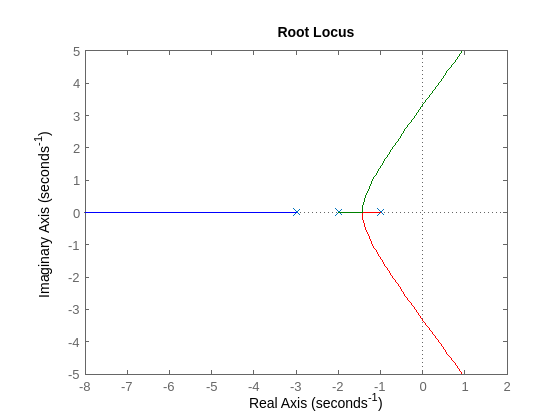

figure(1)
rlocus(G)

**Plotting the location of the desired poles**

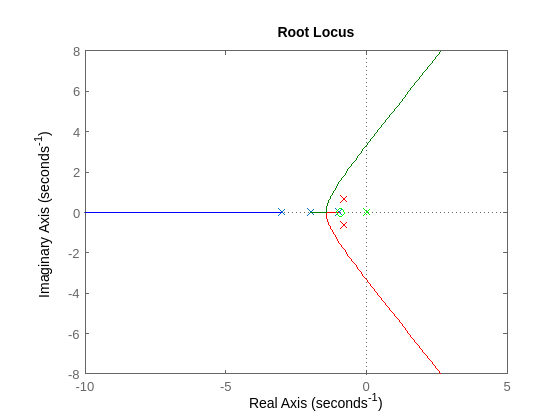

figure(3)
rlocus(G)
hold on
xlim([-10 5])
ylim([-8 8])
plot(pd,'rx')
plot(zc,0,'go')
plot(pc,0,'gx')
hold off

**closed loop transfer function root locus**

Gn = ((s-zc))/((s+1)*(s+2)*(s+3)*(s-pc))

Gn =
 
          s + 0.9321
  --------------------------
  s^4 + 6 s^3 + 11 s^2 + 6 s
 
Continuous-time transfer function.
Model Properties


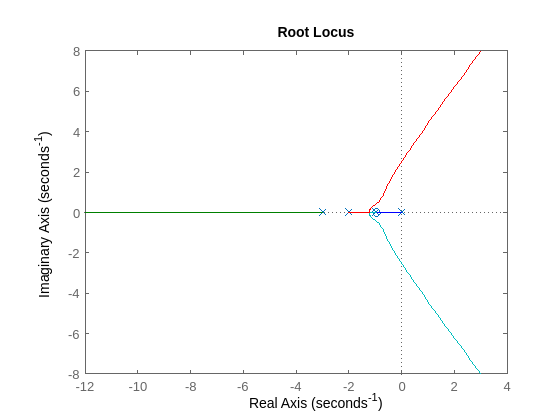

figure(4)
rlocus(Gn)

**Confirming the desired poles are over the root locus.**

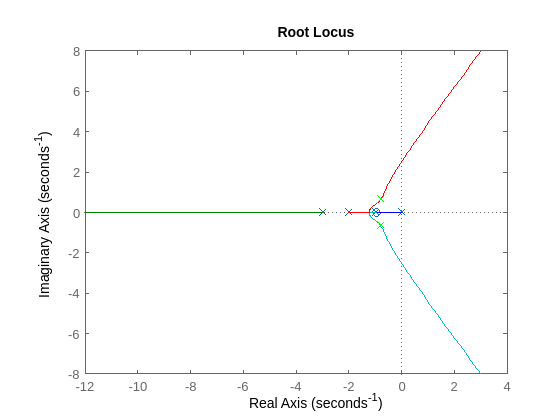

figure(5)
rlocus(Gn)
hold on
plot(pd,'gx')
hold off

Finally the compensator gain K is obtained solving $|\lim_{s\to p_d}[KC(s)G(s)]| =1$ where pd is the desired pole.

kc= 3.28; %obtained value
Gc = kc*((s-zc)/(s-pc))

Gc =
 
  3.28 s + 3.057
  --------------
        s
 
Continuous-time transfer function.
Model Properties


%confirming the desired performance specifications
L=Gc*G;
LC = feedback(L,1);
stepinfo(LC)

ans = struct with fields:
         RiseTime: 2.6610
    TransientTime: 4.3060
     SettlingTime: 4.3060
      SettlingMin: 0.9041
      SettlingMax: 1.0088
        Overshoot: 0.8787
       Undershoot: 0
             Peak: 1.0088
         PeakTime: 5.8110


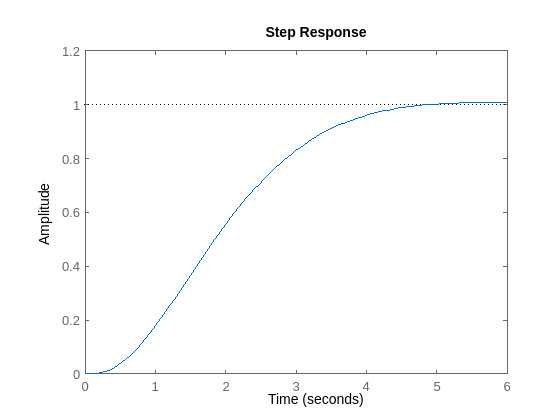

step(LC)